# Example of four wave mixing simulation with LaserPulse class

Create a new pulse in time domain.

% pulse parameters
n = 2^12; dt = 0.2; s = 10; t0 = 10; f0 = 0.4;
% time array
t = (-n/2:n/2-1).' * dt;
% electric field
Et = exp(-(t-t0).^2/s^2 -2i*pi*t*f0);
% LaserPulse object
p1 = LaserPulse(t, 'ns', Et);
p1.normalize()

The four-wave-mixing (FWM) signal can be directly calculated in the time domain:

p1.activeDomain = 'time'; % this line can be skipped as it is the default setting
pfwm = p1.^2 .* conj(p1);

The frequency domain field is automatically calculated behind the scenes and can be easily plotted:

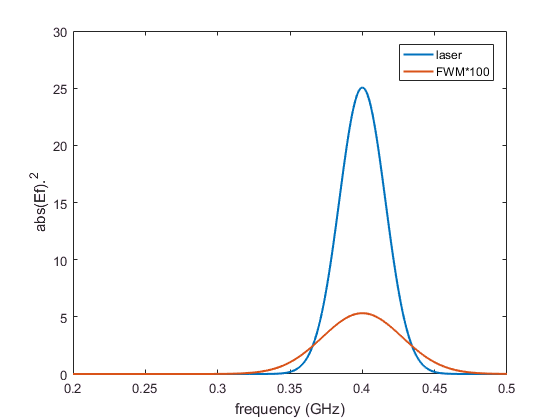

figure();
plot(p1.frequencyArray,p1.spectralIntensity, ...
  pfwm.frequencyArray,pfwm.spectralIntensity*100, ...
  'LineWidth', 1.5);
xlabel(['frequency (', p1.frequencyUnits, ')']);
ylabel('abs(Ef).^2'); axis([0.2 0.5 0 30])
legend('laser', 'FWM*100');